# **Load and Extract Text Data**

Data_T=readtable("New classification\Training data.xlsx","TextType","string")

Data_T = 9417×2 table
             Measure_Name                                                              Description                                                 
    ______________________________    _____________________________________________________________________________________________________________

    "Bulb - Exterior"                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    "Bulb - Exterior"                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    "Bulb - Exterior"                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    "Lighting Controls - Exterior"    ""(1) 2-pole circuit dimmer lighting""                                                                       
    "VFD - Cooling"  


% Convert the labels in the PROGRAM column 
Data_T.Measure_Name=categorical(Data_T.Measure_Name)

Data_T = 9417×2 table
            Measure_Name                                                             Description                                                 
    ____________________________    _____________________________________________________________________________________________________________

    Bulb - Exterior                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    Bulb - Exterior                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    Bulb - Exterior                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    Lighting Controls - Exterior    ""(1) 2-pole circuit dimmer lighting""                                                                       
    VFD - Cooling                

# **Cross-Validation**

% Partition data into sets for training and validation
cvp = cvpartition(Data_T.Measure_Name,'Holdout',0.1,'Stratify',false)

cvp = Hold-out cross validation partition
   NumObservations: 9417
       NumTestSets: 1
         TrainSize: 8476
          TestSize: 941

dataTrain = Data_T(cvp.training,:)

dataTrain = 8476×2 table
            Measure_Name                                                             Description                                                 
    ____________________________    _____________________________________________________________________________________________________________

    Bulb - Exterior                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    Bulb - Exterior                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    Lighting Controls - Exterior    ""(1) 2-pole circuit dimmer lighting""                                                                       
    VFD - Cooling                   ""(1) 20 hp vfd on closed-circuit cooler fan motor cooling""                                                 
    Air Source                

dataValidation  = Data_T(cvp.test,:)

dataValidation = 941×2 table
           Measure_Name                                              Description                                   
    ___________________________    ________________________________________________________________________________

    Bulb - Exterior                ""(1) 12w ledt8 lamp + 1l ballast lighting""                                    
    ECM Motor - HVAC               ""(1) grundfos alpha 15-55f ecm hw pump heating""                               
    Furnace                        ""(12) heil model # n95esn080 2120a condensing furnaces, 96% efficient heating""
    LED Linear - Upstream          ""(2) 10t8/48-4000-if-10/1 w/ (1) icn2p16tledn35m ele driver lighting""         
    LED Screw In - Upstream        ""(2) 3.5w led candelabra screw-in lighting""                                   
    LED Linear - Upstream          ""(2) 9t8led/36-4000-if-10/1 469346 w/icn2p16tledn35m e


textDataTrain=dataTrain.Description

textDataTrain = 8476×1 string array
    ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""
    ""(1) 16.5w ledt8 lamp + 1h ballast lighting""
    ""(1) 2-pole circuit dimmer lighting""
    ""(1) 20 hp vfd on closed-circuit cooler fan motor cooling""
    ""(1) air source heat pump cooling""
    ""(1) air source heat pump heating""
    ""(1) cm-9 & (1) pp-20 low voltage ceiling sensor lighting""
    ""(1) cm-9 & (1) pp-20-2p low voltage ceiling sensor (2 circuits) lighting""
    ""(1) door heater cntrl. (humidity sensor + control); (0) relays) refrigeration""
    ""(1) door heater cntrl. (humidity sensor + control); (2 relays) refrigeration""
    ""(1) door heater cntrl. (humidity sensor + control); (2) relays) refrigeration""
    ""(1) dual enthalpy economizer cooling""
    ""(1) dual tech wall sensor - 2 pole (includes the cost for the double gang satin stainless plate) lighting""
    ""(1) ductless heat pump  lg #lsu180hsv5 cooling""
    ""(1) ductless heat pump

textDataValidation=dataValidation.Description

textDataValidation = 941×1 string array
    ""(1) 12w ledt8 lamp + 1l ballast lighting""
    ""(1) grundfos alpha 15-55f ecm hw pump heating""
    ""(12) heil model # n95esn080 2120a condensing furnaces, 96% efficient heating""
    ""(2) 10t8/48-4000-if-10/1 w/ (1) icn2p16tledn35m ele driver lighting""
    ""(2) 3.5w led candelabra screw-in lighting""
    ""(2) 9t8led/36-4000-if-10/1 469346 w/icn2p16tledn35m ele driver (2) lighting""
    ""(2) air source heat pumps heating""
    ""(2) cwp vfds cooling""
    ""(2) espen ballasted 4' led t5 lighting""
    ""(2) new track assemblies w/ (3) new 12w par30 led lamps each lighting""
    ""(2) philips 10t8/48-4000-if-10/1 & (1) advance icn2p16tledn35m lighting""
    ""(2) programmable thermostat cooling""
    ""(4) 10t8/48-4000-if-10/1 468280 w/icn2p16tledn35m ele driver lighting""
    ""(4) t5 led tube and ballast lighting""
    ""(6) eco-optimizer demand control ventilation heating""
    "".50 inch pipe insulation domestic hot water""
    ""

YTrain = dataTrain.Measure_Name

YTrain = 8476×1 categorical array
     Bulb - Exterior 
     Bulb - Exterior 
     Lighting Controls - Exterior 
     VFD - Cooling 
     Air Source 
     Air Source 
     Lighting System - Exterior 
     Lighting System - Exterior 
     Hotel Occupancy Sensor 
     Hotel Occupancy Sensor 
     Hotel Occupancy Sensor 
     Economizer 
     Lighting System - Exterior 
     Ductless 
     Ductless 
     Lighting Fixture - Upstream 
     Lighting Fixture - Upstream 
     Furnace 
     Tankless Water Heater 
     Boiler 
     Tankless Water Heater 
     Lighting System - Exterior 
     LED Linear - Upstream 
     Variable Speed Drive 
     Lighting System - Interior 
     Lighting Fixture - Upstream 
     Economizer 
     Thermostat 
     Thermostat 
     Lighting Fixture - Upstream 


YValidation=dataValidation.Measure_Name

YValidation = 941×1 categorical array
     Bulb - Exterior 
     ECM Motor - HVAC 
     Furnace 
     LED Linear - Upstream 
     LED Screw In - Upstream 
     LED Linear - Upstream 
     Air Source 
     VFD - Cooling 
     LED Linear - Upstream 
     LED Screw In - Upstream 
     LED Linear - Upstream 
     Thermostat 
     LED Linear - Upstream 
     LED Linear - Upstream 
     Demand Control Ventilation 
     Pipe Insulation - Hot Water 
     Door Heater Control 
     Sustainable Office Design 
     Novelty Cooler Control 
     Sustainable Office Design 
     Pipe Insulation - Hot Water 
     Pipe Insulation - Hot Water 
     Pipe Insulation - Hot Water 
     Fee 
     LED Linear - Upstream 
     LED Fixture - Upstream 
     Lighting Controls - Interior 
     Lighting Controls - Interior 
     Lighting System - Exterior 
     Lighting System - Exterior 


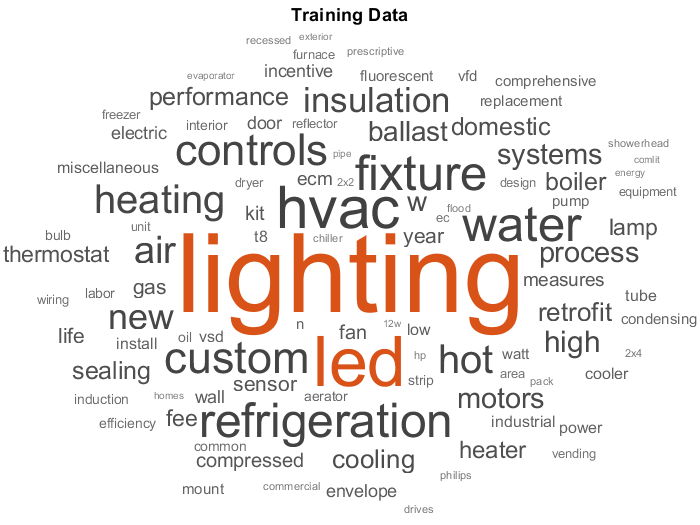


figure
wordcloud(textDataTrain);
title("Training Data")

# **Preprocessing**

DATATrain=preprocessText(textDataTrain);
DATAVtest=preprocessText(textDataValidation);

# **Train Supervised Classifier**

bag = bagOfWords(DATATrain)

bag =   bagOfWords with properties:

          Counts: [8476×5944 double]
      Vocabulary: [1×5944 string]
        NumWords: 5944
    NumDocuments: 8476


bag = removeInfrequentWords(bag,1);
[bag,idx] = removeEmptyDocuments(bag);
YTrain(idx) = [];
bag

bag =   bagOfWords with properties:

          Counts: [8476×2651 double]
      Vocabulary: [1×2651 string]
        NumWords: 2651
    NumDocuments: 8476



XTrain = bag.Counts;
mdl = fitcecoc(XTrain,YTrain,'Learners','linear')

mdl =   classreg.learning.classif.CompactClassificationECOC
      ResponseName: 'Y'
        ClassNames: [1×128 categorical]
    ScoreTransform: 'none'
    BinaryLearners: {8128×1 cell}
      CodingMatrix: [128×8128 double]


  Properties, Methods


# **Traditonal Classification Model**

DATAVtest=preprocessText(textDataValidation)

DATAVtest =   941×1 tokenizedDocument:

     6 tokens: 12w ledt8 lamp 1l ballast lighting
     7 tokens: grundfos alpha 1555f ecm hw pump heating
    10 tokens: 12 heil model n95esn080 2120a condensing furnaces 96 efficient heating
     5 tokens: 10t8484000if101 icn2p16tledn35m ele driver lighting
     5 tokens: 35w led candelabra screwin lighting
     7 tokens: 9t8led 364000if101 469346 icn2p16tledn35m ele driver lighting
     5 tokens: air source heat pumps heating
     3 tokens: cwp vfds cooling
     5 tokens: espen ballasted led t5 lighting
     9 tokens: new track assemblies new 12w par30 led lamps lighting
     5 tokens: philips 10t8484000if101 advance icn2p16tledn35m lighting
     3 tokens: programmable thermostat cooling
     6 tokens: 10t8484000if101 468280 icn2p16tledn35m ele driver lighting
     5 tokens: t5 led tube ballast lighting
     5 tokens: ecooptimizer demand control ventilation heating
     7

XTest = encode(bag,DATAVtest);


YPred = predict(mdl,XTest);
acc = sum(YPred == YValidation)/numel(YValidation)

acc = 0.8927

# **Predict Using New Data**

newdata=readtable("data\test1.xlsx","TextType","string")

newdata = 1048575×1 table
                               Description                           
    _________________________________________________________________

    "REFRIGERATION REFRIGERATOR REFRIGERATOR FOR APPLIANCE PROGRAM |"
    "REFRIGERATION REFRIGERATOR REFRIGERATOR_RECYCLE |"              
    "REFRIGERATION FREEZER RECYCLE FREEZER_RECYCLE |"                
    "REFRIGERATION FREEZER REBATE FREEZER FOR APPLIANCES PROGRAM |"  
    "REFRIGERATION REFRIGERATOR REFRIGERATOR FOR APPLIANCE PROGRAM |"
    "REFRIGERATION REFRIGERATOR REFRIGERATOR FOR APPLIANCE PROGRAM |"
    "REFRIGERATION REFRIGERATOR REFRIGERATOR FOR APPLIANCE PROGRAM |"
    "REFRIGERATION REFRIGERATOR CHANGE OUT 15 CUFT FRIGIDAIRE CF |"  
    "REFRIGERATION REFRIGERATOR REFRIGERATOR_RECYCLE |"              
    "REFRIGERATION TOP TEN FRIDGE TOP TEN FRIDGE |"                  
    "REFRIGERATION FREEZER RECYCLE FREEZER_RECYCLE |"                
    "REFRIGERATION REFRIGERAT

newdataD=newdata_CL.Whole_Data_unique

newdataD = 248×1 string array
    ""all aerators and showerheads other""
    ""domestic hot water measures | hot water | dhw_showerhead_gas | showerhead (1.75 gpm) | 3000.161 hot water""
    ""domestic hot water | showerheads | showerhead hot water""
    ""hand held shower head domestic hot water""
    ""hand held shower head none""
    ""hand held shower head water""
    ""hand held showerhead (3 gpm) domestic hot water""
    ""hand held showerhead (3 gpm) none""
    ""hand held showerhead (3 gpm) water""
    ""hand held showerhead (3.5 gpm) domestic hot water""
    ""hand held showerhead (3.5 gpm) none""
    ""hand held showerhead (3.5 gpm) water""
    ""hand held showerhead (4 gpm) domestic hot water""
    ""hand held showerhead (4 gpm) water""
    ""hand held showerhead (4.5 gpm) domestic hot water""
    ""hand held showerhead (4.5 gpm) water""
    ""hand held showerhead (5 gpm) domestic hot water""
    ""hand held showerhead (5 gpm) water""
    ""hand held showerhead domestic hot 


dataNew = preprocessText(newdataD);
XNew = encode(bag,dataNew)

XNew =    (5,6)        1
   (8,6)        1
  (11,6)        1
  (20,6)        1
  (52,6)        1
  (51,28)       1
  (52,28)       1
  (53,28)       1
  (54,28)       1
  (55,28)       1
  (56,28)       1
 (243,28)       1
 (248,28)       1
 (248,37)       1
   (2,62)       3
   (3,62)       2
   (4,62)       1
   (6,62)       1
   (7,62)       1
   (9,62)       1
  (10,62)       1
  (12,62)       1
  (13,62)       1
  (14,62)       1
  (15,62)       1
  (16,62)       1
  (17,62)       1
  (18,62)       1
  (19,62)       1
  (21,62)       1
  (22,62)       1
  (23,62)       2
  (24,62)       2
  (25,62)       2
  (26,62)       2
  (27,62)       2
  (28,62)       2
  (29,62)       2
  (30,62)       2
  (31,62)       2
  (32,62)       2
  (33,62)       2
  (34,62)       2
  (35,62)       2
  (36,62)       2
  (37,62)       2
  (38,62)       2
  (39,62)       2
  (40,62)       2
  (41,62)       2
  (42,62)       2
  (43,62)       2
  (44,62)       3
  (45,62)       2
  (46,62)       3
  (

labelsNew = predict(mdl,XNew)

labelsNew = 248×1 categorical array
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Tankless Water Heater 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 
     Low Flow Showerhead 



T=table(labelsNew,newdata_CL.Whole_Data_unique)

T = 248×2 table
         labelsNew                                                             Var2                                                     
    ___________________    _____________________________________________________________________________________________________________

    Low Flow Showerhead    ""all aerators and showerheads other""                                                                       
    Low Flow Showerhead    ""domestic hot water measures | hot water | dhw_showerhead_gas | showerhead (1.75 gpm) | 3000.161 hot water""
    Low Flow Showerhead    ""domestic hot water | showerheads | showerhead hot water""                                                  
    Low Flow Showerhead    ""hand held shower head domestic hot water""                                                                 
    Low Flow Showerhead    ""hand held shower head none""                                    

function predata = preprocessText(textData)

predata=lower(textData);
predata=strtrim(predata);
predata=tokenizedDocument(predata);
predata=erasePunctuation(predata);
predata=removeStopWords(predata);
predata=removeShortWords(predata,1);

end